% Number of simulations to average over
numSimulations = 1000;

% Array to hold values of L
L_values = [10, 20, 40, 80, 160, 320, 640, 1280, 2560, 5120, 10240];

% Arrays to store results for the average and standard deviation of the sum of squares of increments
avgSumSquaresIncrements = zeros(size(L_values));
stdSumSquaresIncrements = zeros(size(L_values));

% Loop over different values of L
for j = 1:length(L_values)
    L = L_values(j);
    dt = 2 / L;  % delta t
    
    % Temporary array to store the sum of squares of increments for each simulation
    tempSumSquares = zeros(1, numSimulations);
    
    % Perform simulations
    for i = 1:numSimulations
        % Generate Wiener increments
        dW = sqrt(dt) * randn(1, L);
        
        % Compute the sum of squares of increments
        tempSumSquares(i) = sum(dW.^2);
    end
    
    % Compute the average and standard deviation of the sum of squares of increments
    avgSumSquaresIncrements(j) = mean(tempSumSquares);
    stdSumSquaresIncrements(j) = std(tempSumSquares);
end

% Display the table of L, averages, and standard deviations
T = table(L_values', avgSumSquaresIncrements', stdSumSquaresIncrements', ...
          'VariableNames', {'L', 'Average', 'Standard_Deviation'});
disp(T);

      L      Average    Standard_Deviation
    _____    _______    __________________

       10    2.0442           0.96153     
       20    2.0007           0.65113     
       40    2.0187           0.47457     
       80    1.9903           0.31852     
      160    1.9929           0.22465     
      320    1.9957           0.15678     
      640    1.9995           0.11208     
     1280    1.9972           0.07806     
     2560    2.0022          0.056457     
     5120    1.9987          0.040946     
    10240    1.9997          0.026844     



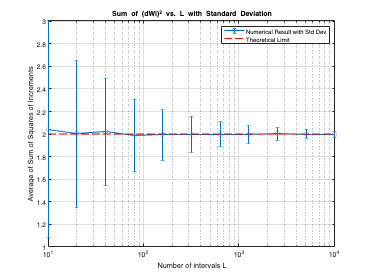


% Plotting the results with error bars
figure;
errorbar(L_values, avgSumSquaresIncrements, stdSumSquaresIncrements, 's-');
xlabel('Number of intervals L');
ylabel('Average of Sum of Squares of Increments');
title('Sum of (dWi)^2 vs. L with Standard Deviation');
set(gca, 'XScale', 'log');
grid on;
hold on;
plot(L_values, repmat(2, size(L_values)), 'r--'); % Line at the theoretical limit 2
legend('Numerical Result with Std Dev', 'Theoretical Limit');